# 1.经验最大值问题

clc,clear;
f = [-20;-30,;-45];
A = [4,8,15;1,1,1;];
b = [100;20];
lb = zeros(3,1);
% 没有等式约束
[x,fval] = linprog(f,A,b,[],[],lb)

找到最优解。



x =     15
     5
     0


fval = -450

% 目标函数最大化
y = -fval

y = 450

disp('A、B、C三图分别通关的次数:')

A、B、C三图分别通关的次数:


disp(x)

    15
     5
     0



disp('最后获得的经验为:')

最后获得的经验为:


disp(y)

   450



# **2.投资收益问题**

clc,clear;
% a矩阵的元素是不同的风险率,从0,0.05等差取值
% 相邻两个数相差0.001
a = (0:0.001:0.05);
% 目标函数的系数向量
f = [-0.05,-0.27,-0.19,-0.185,-0.185];
% A是不等式的约束条件的变量系数构成的矩阵
% 用zeros(4,1)先构造4行1列的全是0的矩阵,也就是对x_0无约束
%再构造对角矩阵diag([0.025,0.015,0.055,0.026]),对角线上元素为约束条件中的变量系数
A = [zeros(4,1),diag([0.025,0.015,0.055,0.026])];
Aeq = [1,1.01,1.02,1.045,1.065];%等式约束的系数矩阵,也就是所有资产投资
beq = 1;
lb = zeros(5,1);
Q = zeros(1,length(a));%初始化保存最优解的矩阵Q,因为现在还没有求出最优解,元素全设为0
XX = [];%用来存不同风险下的最优解
%利用矩阵Q存储风险率a(i)下的最大收益;for循环中i在变化,风险率a(i)的不同,求出对应的最优解存在矩阵Q中
for i = 1:length(a)%length是矩阵a的元素个数,有多少个元素,就循环多少次
b = a(i)*ones(4,1);%b是约束条件的常数项矩阵,4行一列,每个元素值都是常数a(i)
[x,y] = linprog(f,A,b,Aeq,beq,lb);%调用linprog函数求解线性规划问题
Q(i) = -y;
XX = [XX;x'];
end

找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。



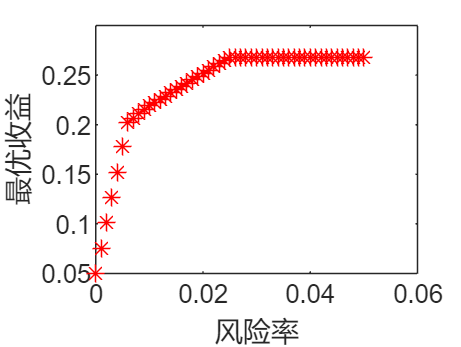

plot(a,Q,'*r');%以风险率为横轴,收益为纵轴,绘制不同风险率下的最优收益
xlabel('风险率');
ylabel(('最优收益'));